# Reflection & Transmission

**• Tangential E is continuous**

    
$$E_i +E_r =E_{\;t} \;\to \;1+\frac{E_r }{\;E_i }=\frac{E_t }{E_i }\;\;\to \;\;1+\Gamma =T$$


Ei = 1 %

Ei = 1

Er = 5 %

Er = 5


Et    = Ei+Er 

Et = 6

T     = 1+Er/Ei

T = 6

Gamma = Et/Ei-1

Gamma = 5

**• Tangential H is continuousa**

Hi = 1 %

Hi = 1

Hr = 5 %

Hr = 5


Ht    = Hi+Hr 

Ht = 6

T     = 1+Hr/Hi

T = 6

Gamma = Ht/Hi-1

Gamma = 5

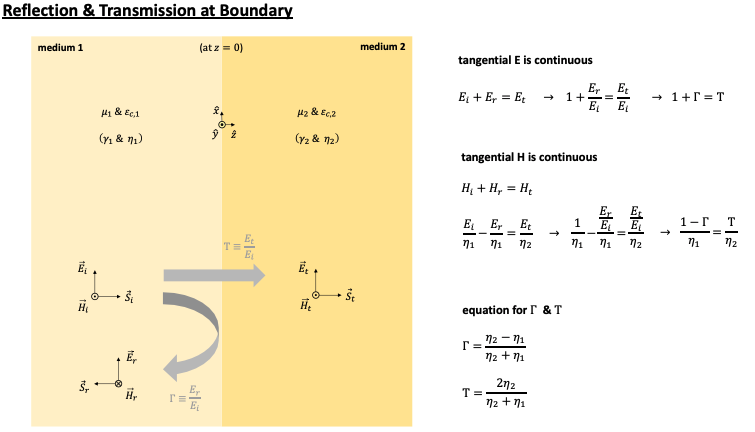

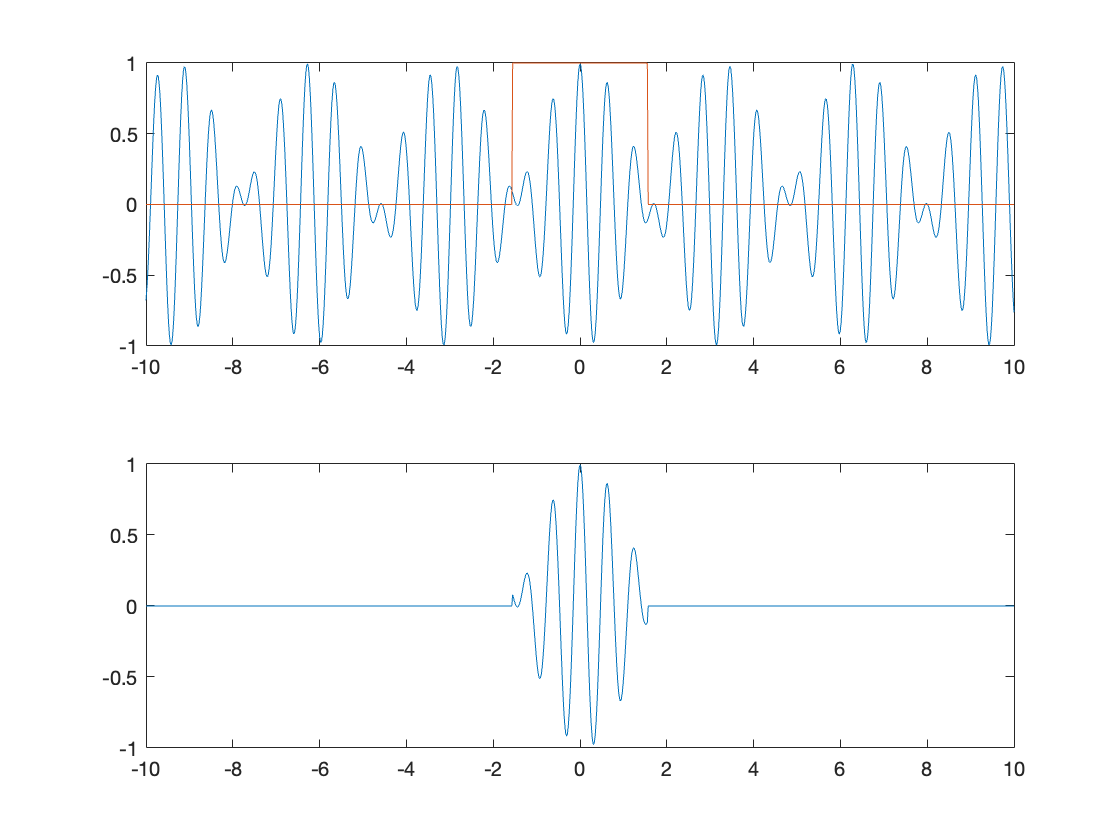

clc; clear all; 

x =   10; %  
w = 10; % 
b = 0.1; % 
z = 0.1; % 

x0 = fzero(@(x) fun(x),3);
x3 = linspace(-x0,x0,1000);
x = linspace(-x,x,1000);
y = cos(w.*x-z.*b).*cos(x-z);
y1= heaviside(x+x0)-heaviside(x-x0);
y2= y.*y1;
tiledlayout(2,1)
ax1 = nexttile;
plot(x,y,x,y1);
ax2 = nexttile;
plot(x,y2);

function y3= fun(x)
    y3 = 2.*cos(x);
end












